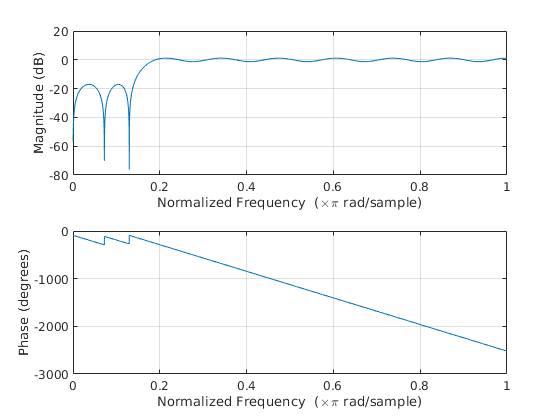

clear; clc; close all; format long;

Fs = 100000000;
samp = 32;
n=100;
t=0:1/Fs:(n-1)/Fs;
f0=9000000;                       % Center frequency of BPF
f1=5000000;
f0_low=99000;                   % Upper frequency of BPF
f0_high=101000;                  % Lower frequency of BPF
Wn=[f0/Fs*2];  % Cut off frequencies (0 < Wn < 1)
%B=fir1(samp-1,Wn,'high');        % Create filter coefficients
B=firpm(samp-1,[0 0.14 0.18 1],[0 0 1 1],'h');
figure,freqz(B,1,4096)

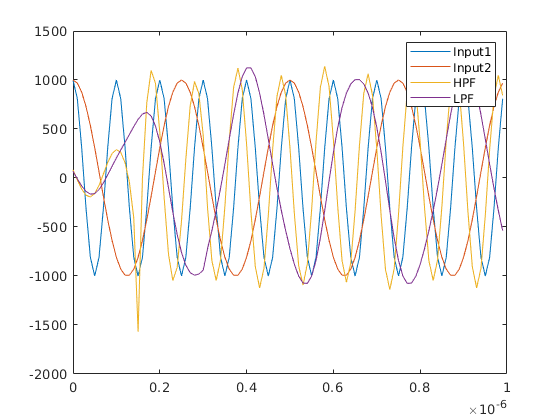


% file=fopen('high_pass.txt','wt');
% for k=1:length(B)
%     fprintf(file,"%f ",B(k));
% end

Wn=f1/Fs*2;
%BB=fir1(samp-1,Wn,'low');
BB=firpm(samp-1,[0 0.1 0.15 1],[1 1 0 0]);

% file=fopen('low_pass.txt','wt');
% for k=1:length(BB)
%     fprintf(file,"%f ",BB(k));
% end

x1=1000*cos(10000000*2*pi*t);
x2=1000*cos(4000000*2*pi*t);
x=x1+x2;
y = filter(B,1,x);
yy = filter(BB,1,x);
figure,plot(t(1:n),x1(1:n)),hold on,plot(t(1:n),x2(1:n)),plot(t(1:n),y(1:n))
plot(t(1:n),yy(1:n)),legend('Input1','Input2','HPF','LPF')

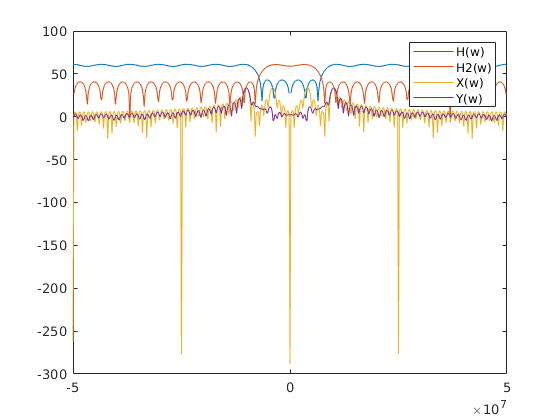


nfft = 4*2^nextpow2(length(t));
H = abs(fftshift(freqz(1000*B,1,nfft,'whole')));
H2= abs(fftshift(freqz(1000*BB,1,nfft,'whole')));
X = abs(fftshift(fft(x/1000,nfft)));
Y = abs(fftshift(fft(y/1000,nfft)));
F = (-nfft/2:nfft/2-1)/nfft*Fs;   % Actual frequency F
figure,plot(F,20*log10(H)),hold on,plot(F,20*log10(H2)),plot(F,20*log10(X))
plot(F,20*log10(Y)),legend('H(w)','H2(w)','X(w)','Y(w)')